clear all

% Params
fs = 8e3;

% 1 - LP IIR filter design
% Spec - filterDesigner
% 2 - BP IIR filter design
% Spec - filterDesigner
% 3 - HP IIR filter design
% Spec - filterDesigner

% 4/7/10/13 - Impulse, Mag, Phase, PZ before
load('LP.mat')
[LP_B, LP_A] = sos2tf(SOS_LP, G_LP)

LP_B =     0.0064   -0.0103    0.0272   -0.0241    0.0397   -0.0260    0.0397   -0.0241    0.0272   -0.0103    0.0064


LP_A =     1.0000   -5.7725   17.4692  -34.7196   49.5599  -52.6145   41.9489  -24.7834   10.4177   -2.8329    0.3856


%fvtool(LP_B,LP_A)

% 5/8/11/14 - Impulse, Mag, Phase, PZ before
load('BP.mat')
[BP_B, BP_A] = sos2tf(SOS_BP, G_BP)

BP_B =     0.0070    0.0000    0.0029    0.0000    0.0179    0.0000    0.0008    0.0000    0.0206    0.0000    0.0008    0.0000    0.0179    0.0000    0.0029    0.0000    0.0070


BP_A =     1.0000    0.0000    4.6629    0.0000   11.3119    0.0000   17.5548    0.0000   18.8504   -0.0000   14.2178   -0.0000    7.3596   -0.0000    2.4004   -0.0000    0.3847


%fvtool(BP_B,BP_A)

% 6/9/12/15 - Impulse, Mag, Phase, PZ before
load('HP.mat')
[HP_B, HP_A] = sos2tf(SOS_HP, G_HP)

HP_B =     0.0794   -0.5344    1.8160   -3.9979    6.2562   -7.2359    6.2562   -3.9979    1.8160   -0.5344    0.0794


HP_A =     1.0000   -2.6176    5.7601   -7.1077    7.8578   -5.4854    3.8542   -1.5627    0.9484   -0.2321    0.1559


%fvtool(HP_B,HP_A)

% 16 - LP quant PZ
q_float = quantizer('single'); % Convert to signle precision
LP_A_q = quantize(q_float, LP_A);
LP_B_q = quantize(q_float, LP_B);
%fvtool(LP_B_q, LP_A_q)

% 17 - BP quant PZ
q_float = quantizer('single'); % Convert to signle precision
BP_A_q = quantize(q_float, BP_A);
BP_B_q = quantize(q_float, BP_B);
%fvtool(BP_B_q, BP_A_q)

% 18 - HP quant PZ
q_float = quantizer('single'); % Convert to signle precision
HP_A_q = quantize(q_float, HP_A);
HP_B_q = quantize(q_float, HP_B);
fvtool(HP_B_q, HP_A_q)

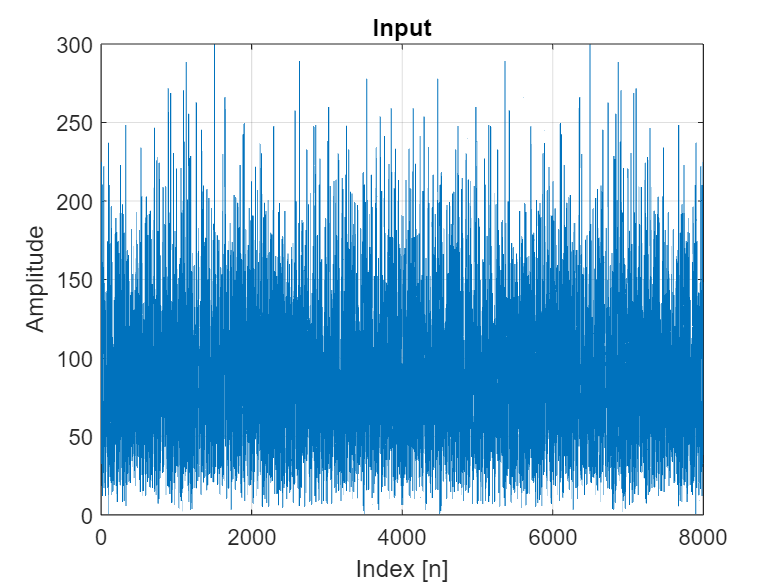

% 19 - LP WGN Frq
x = wgn(10000,1,0); % Gaussian noise (mean = 0, std = 1)

figure;
plot(fs*[0:1/length(x):(length(x)-1)/length(x)], abs(fft(x)));
xlabel('Index [n]');
ylabel('Amplitude');
title('Input');
grid on;

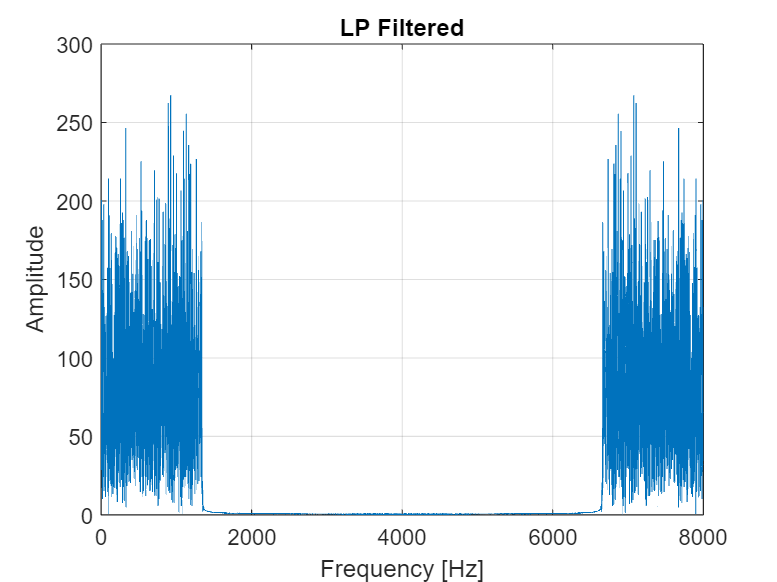


y_lp = filter(LP_B_q, LP_A_q, x);

figure;
plot(fs*[0:1/length(y_lp):(length(y_lp)-1)/length(y_lp)], abs(fft(y_lp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('LP Filtered'); % Two-sided
grid on;

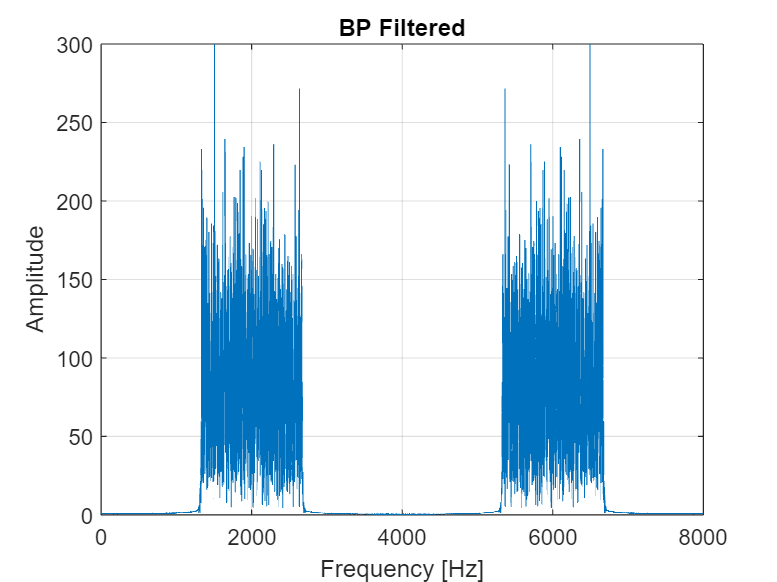


% 20 - BP WGN Frq
y_bp = filter(BP_B_q, BP_A_q, x);

figure;
plot(fs*[0:1/length(y_bp):(length(y_bp)-1)/length(y_bp)], abs(fft(y_bp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('BP Filtered'); % Two-sided
grid on;

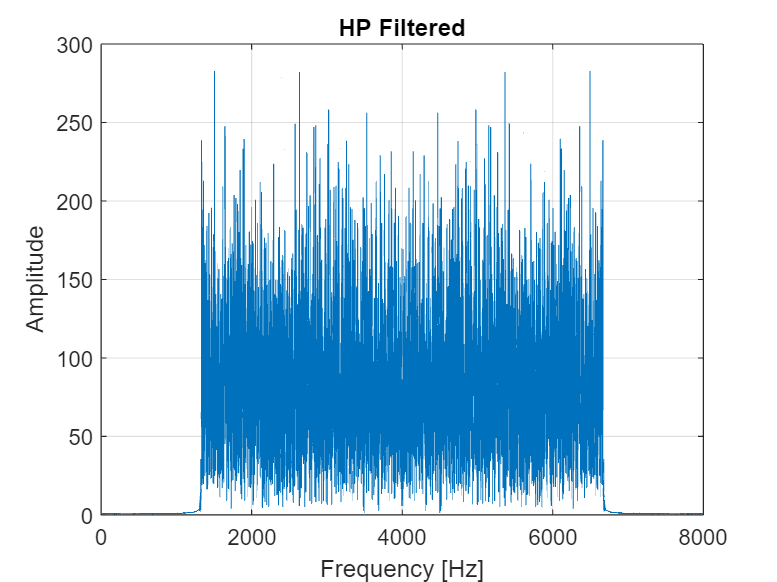


% 21 - HP WGN Frq
y_hp = filter(HP_B_q, HP_A_q, x);

figure;
plot(fs*[0:1/length(y_hp):(length(y_hp)-1)/length(y_hp)], abs(fft(y_hp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('HP Filtered'); % Two-sided
grid on;

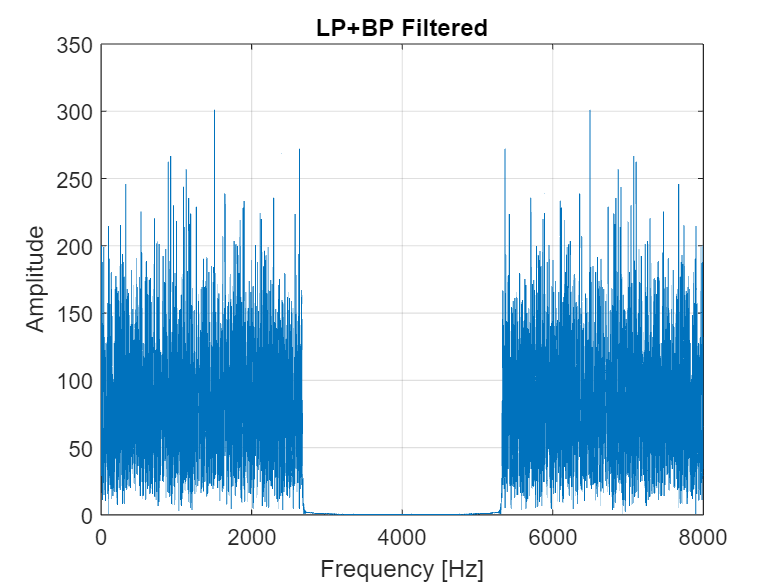


% 22 - LP+BP WGN Frq
y_lp = filter(LP_B_q, LP_A_q, x);
y_bp = filter(BP_B_q, BP_A_q, x);
y_lp_bp = y_lp+y_bp;

figure;
plot(fs*[0:1/length(y_lp_bp):(length(y_lp_bp)-1)/length(y_lp_bp)], abs(fft(y_lp_bp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('LP+BP Filtered'); % Two-sided
grid on;

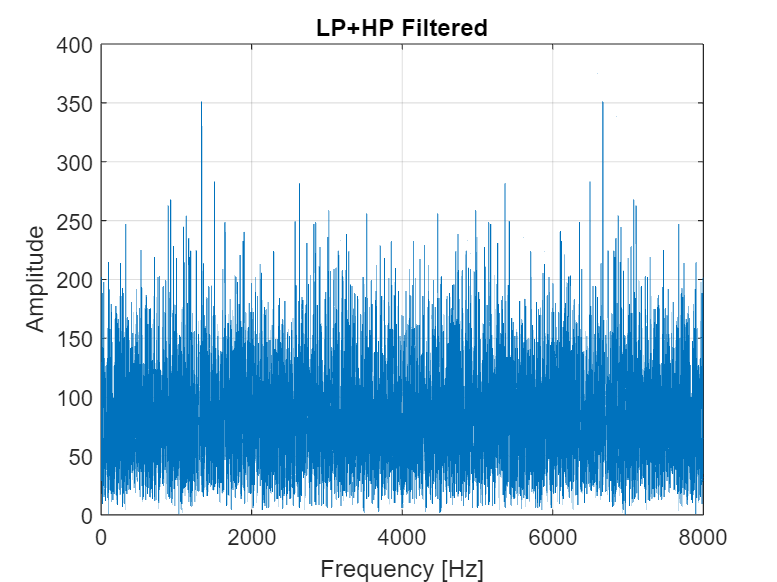

% 23 - LP+HP WGN Frq
y_lp = filter(LP_B_q, LP_A_q, x);
y_hp = filter(HP_B_q, HP_A_q, x);
y_lp_hp = y_lp+y_hp;

figure;
plot(fs*[0:1/length(y_lp_hp):(length(y_lp_hp)-1)/length(y_lp_hp)], abs(fft(y_lp_hp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('LP+HP Filtered'); % Two-sided
grid on;

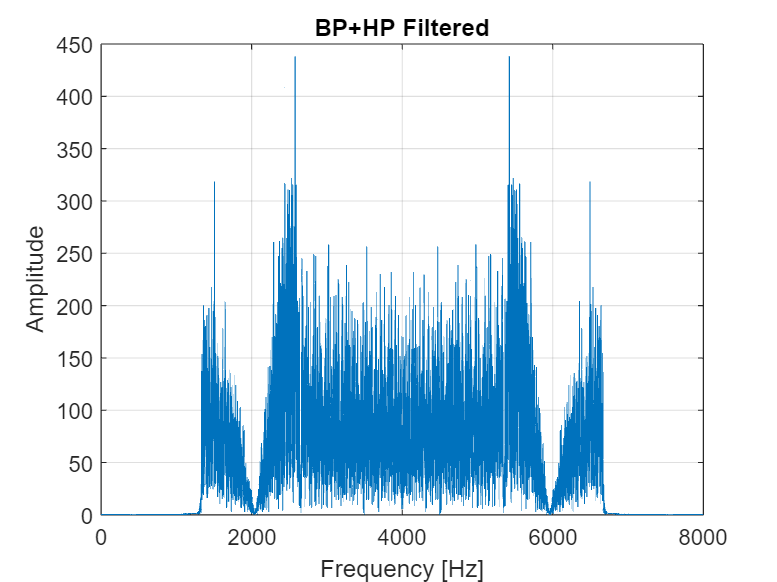


% 24 - BP+HP WGN Frq
y_bp = filter(BP_B_q, BP_A_q, x);
y_hp = filter(HP_B_q, HP_A_q, x);
y_bp_hp = y_bp+y_hp;

figure;
plot(fs*[0:1/length(y_bp_hp):(length(y_bp_hp)-1)/length(y_bp_hp)], abs(fft(y_bp_hp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('BP+HP Filtered'); % Two-sided
grid on;

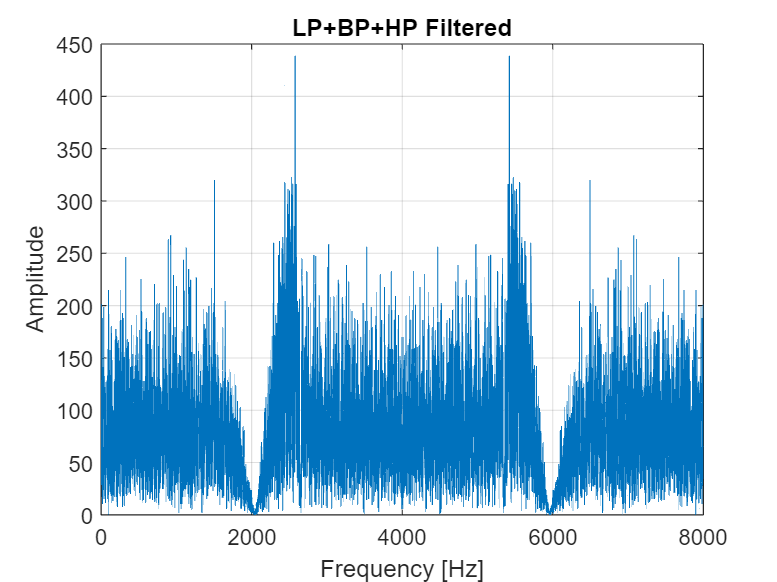


% 25 - BP+HP WGN Frq
y_lp = filter(LP_B_q, LP_A_q, x);
y_bp = filter(BP_B_q, BP_A_q, x);
y_hp = filter(HP_B_q, HP_A_q, x);
y_lp_bp_hp = y_lp+y_bp+y_hp;

figure;
plot(fs*[0:1/length(y_lp_bp_hp):(length(y_lp_bp_hp)-1)/length(y_lp_bp_hp)], abs(fft(y_lp_bp_hp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('LP+BP+HP Filtered'); % Two-sided
grid on;